# **Amar Ramdas - 4461487**

## **Exercise 1:**

P7.1. Write a program that illustrates the timescale invariance of the asset model, in the style of Figure 7.5

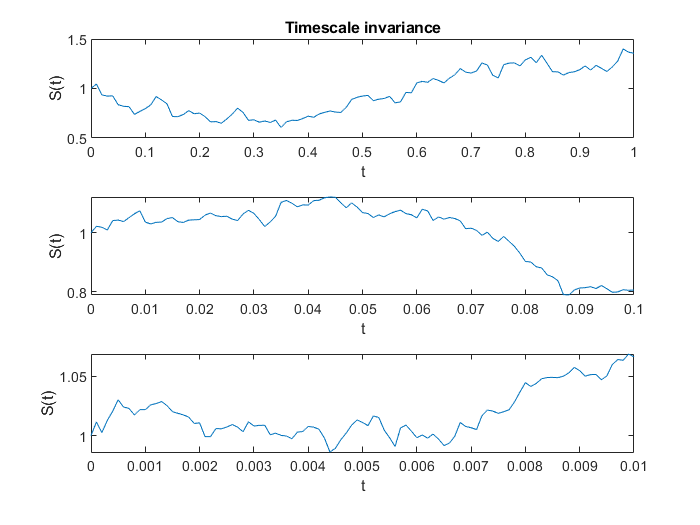

%CH07 Program for Chapter 7 % % Plot discrete sample paths
randn('state',100) ;
clf

%%%%%%%%% Problem parameters %%%%%%%%%%
S=1; mu=0.05; sigma = 0.5; L = 1e2; 

for i = 0:2
    T = 10^-i; 
    dt =T/L; M = 1; 

    tvals = [0:dt:T]; 
    Svals = S*cumprod(exp((mu-0.5*sigma^2)*dt + sigma*sqrt(dt)*randn(M,L)),2); 
    Svals = [S*ones(M,1) Svals]; % add initial asset price 
    
    
    h(i+1) = subplot(3,1,i+1);
        
    plot(tvals,Svals)
    xlabel('t'), ylabel('S(t)')
    
    if i==0
            title('Timescale invariance') 
    end

end 

**Exercise 2:**

Solve Exercise 8.10 from the book by Higham, page 83

**Exercise 3:**

studentno = 4461487;
mu = studentno;

%divide mu by 10 until mu<0.1
while mu>0.1
mu = mu / 10;
end

mu

mu = 0.0446

sigma = mu*4

sigma = 0.1785


%using matlab Brownian Motion function
BM = bm(mu, sigma)

BM =    Class BM: Brownian Motion
   ----------------------------------------
     Dimensions: State = 1, Brownian = 1
   ----------------------------------------
      StartTime: 0
     StartState: 0
    Correlation: 1
          Drift: drift rate function F(t,X(t)) 
      Diffusion: diffusion rate function G(t,X(t)) 
     Simulation: simulation method/function simByEuler
             Mu: 0.0446149
          Sigma: 0.178459